syms theta1 theta2 theta3 a1 d3;

% theta1  = 0-60
% theta2 = 0-40
% theta3 = 0-20
% step size  = 5;
%a1  = 100 mm
%d3 = 20 mm

T01 = get_DH_matrix(a1,0,0,theta1);
T12 = get_DH_matrix(0,deg2rad(90),0,deg2rad(90)+theta2);
T2H = get_DH_matrix(0,0,d3,theta3);

T_eef = T01*T12*T2H;
tool_x = [];
tool_y = [];
tool_z = [];
nu = [];
nv = [];
nw = [];
ou = [];
ov = [];
ow = [];
au = [];
av = [];
aw = [];

for i = 0:5:60
    for j = 0:5:40
        for k = 0:5:20
            mat = subs(T_eef,[a1,d3,theta1,theta2,theta3],[100,20,deg2rad(i),deg2rad(j),deg2rad(k)]);
            coord = mat(1:3,4);
            tool_x = [tool_x coord(1)];
            tool_y = [tool_y coord(2)];
            tool_z = [tool_z coord(3)];
            nu  = [nu mat(1,1)];
            nv = [nv mat(2,1)];
            nw = [nw mat(3,1)];
            ou  = [ou mat(1,2)];
            ov = [ov mat(2,2)];
            ow = [ow mat(3,2)];
            au  = [au mat(1,3)];
            av = [av mat(2,3)];
            aw = [aw mat(3,3)];
        end
    end
    disp('Iteration done');
   
end

Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done
Iteration done


disp('done');

done


figure;

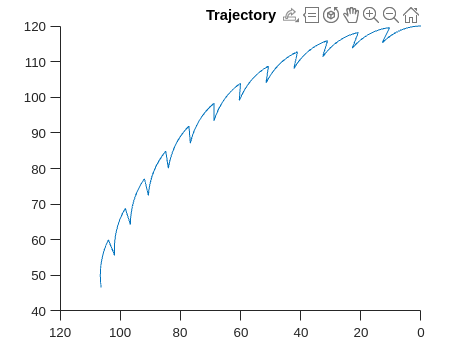

plot3(tool_x,tool_y,tool_z);
title('Trajectory');

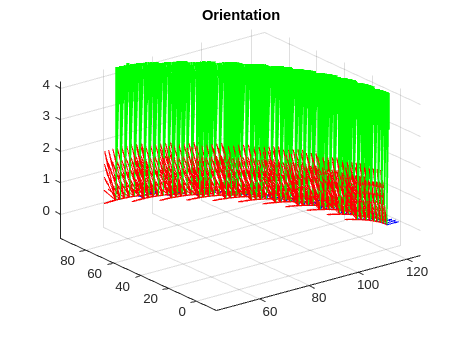

quiver3(tool_x,tool_y,tool_z,nu,nv,nw,'r');
hold on;
quiver3(tool_x,tool_y,tool_z,ou,ov,ow,'g');
quiver3(tool_x,tool_y,tool_z,au,av,aw,'b');
hold off;
title('Orientation');

function T = get_DH_matrix(a,alpha,d,theta)
T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
     sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
     0 sin(alpha) cos(alpha) d
     0 0 0 1];
end